# *Assignment 3 -- Frequency Domain Processing*

*Image and Video Processing*

## Ground Rules for the Assignment

- You can only use basic functions (matrix operations, input/output image functions, plotters). Anything else, you need to code from scratch (histogram functions, inverting gamma functions, color matting, histogram equalization).

- The code needs to be appropriately commented and should be reproducible; if we cannot re-generate your figures from your code, we will deduct points.

- The Live Script Report should be detailed and include partial and final soltuions for each exercise. We grade solely the `Report` part; code without report will not be graded, so we encourage that you invest some time on it.

- Interactive plots are welcome, but most important results should be static and generated beforehand.

- Remember to remove all plots and output from the `Task` sections. Only the `Report` should output plots and/or images.

## Submission Details

Simply submit this Live Script with the report inlined as described below. Name the file as `surname1_name1_surname2_name2_assignment3.mlx`

## 1.` Gaussian Filtering [10 points]`

`In this exercise we will be working on filtering and the connection between spatial and frequency domain filtering.`

### `Tasks`

- `Implement Gaussian filtering both in the spatial and frequency domains`

- `Demonstrate that convolving an image with a Gaussian filter with standard deviation `$$\sigma_s$$ `in the spatial domain is equivalent to point-wise multiplication in the frequency domain with Gaussian filter with standard deviation `$$\sigma_f = \frac{1}{2\sigma{s}\pi}$$

- `Analyze how the performance of equivalent filtering in spatial and temporal domains depends on the parameter `$$\sigma_s$$

As described above for Task 1, Gaussian filtering was applied both in the spatial and frequency domains. A test image containing a white square in the middle of a black background was generated to observe the effects of the filters. For spatial filtering, a Gaussian kernel was created using the standard approach and applied via convolution. In the frequency domain, the filtering was performed by multiplying the Fourier transform of the image by a Gaussian-shaped mask with the corresponding frequency-domain standard deviation computed as $$\sigma_f$$= 1 / (2π * $$\sigma_s$$). Several values of $$\sigma_s$$ were tested and for each one, results from both methods were generated and displayed.

The filtered images below show that both spatial and frequency domain approaches yield visually identical outputs, which confirms their equivalence in practical use. As sigma increases, the amount of smoothing grows equally in both cases, and the sharp edges of the square become increasingly blurred. This demonstrates how Gaussian filtering acts as a low-pass filter in both domains.

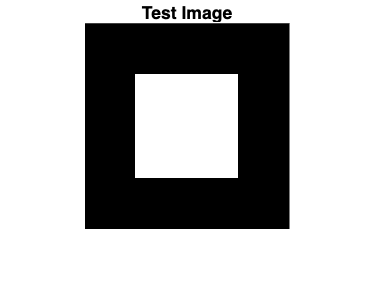

%% Task 1 - Gaussian Filtering (Spatial vs Frequency Domain)

% Generate test image
I = zeros(256, 256);
I(64:192, 64:192) = 1;

figure;
imshow(I, []);
title('Test Image');

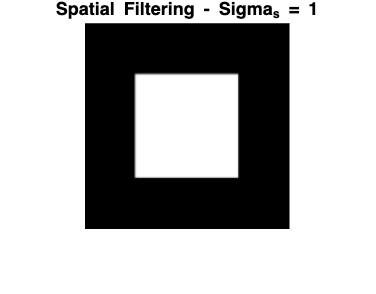

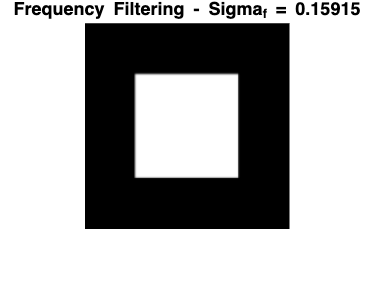

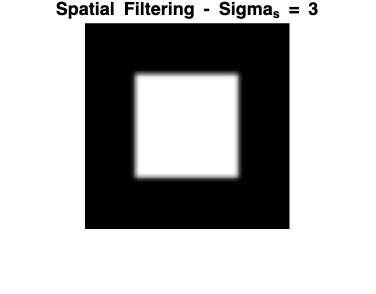

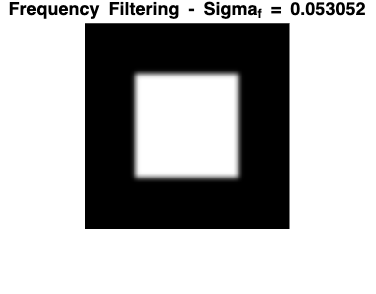

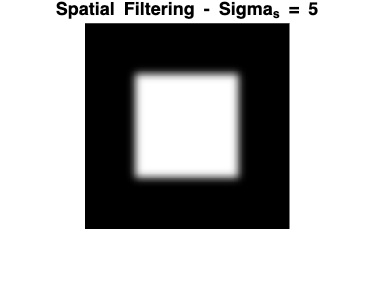

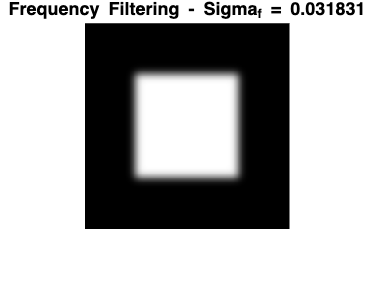


% Define sigma values to test
sigma_s_list = [1, 3, 5];

for sigma_s = sigma_s_list
    
    % --- Spatial domain filtering ---
    hsize = 2 * ceil(3*sigma_s) + 1;
    h = fspecial('gaussian', hsize, sigma_s);
    I_spatial = imfilter(I, h, 'same', 'replicate');
    
    figure;
    imshow(I_spatial, []);
    title(['Spatial Filtering - Sigma_s = ', num2str(sigma_s)]);

    % --- Frequency domain filtering ---
    sigma_f = 1 / (2 * pi * sigma_s);
    [M, N] = size(I);
    [u, v] = meshgrid(-floor(N/2):ceil(N/2)-1, -floor(M/2):ceil(M/2)-1);
    D = sqrt(u.^2 + v.^2);
    H = exp(-(D.^2) / (2 * (sigma_f * N)^2));

    I_fft = fftshift(fft2(I));
    I_filtered_fft = I_fft .* H;
    I_freq = real(ifft2(ifftshift(I_filtered_fft)));

    figure;
    imshow(I_freq, []);
    title(['Frequency Filtering - Sigma_f = ', num2str(sigma_f)]);

end

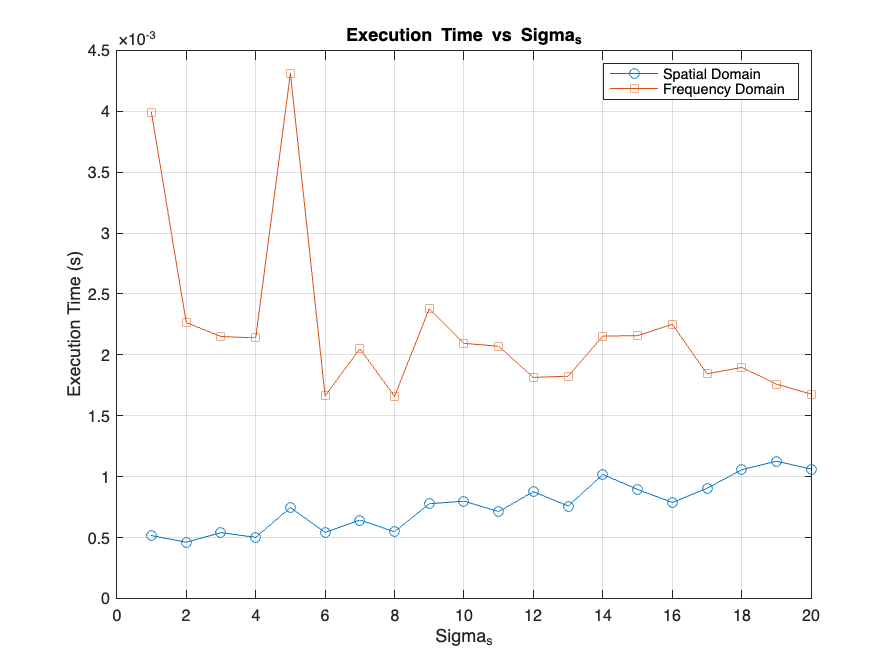


%% --- Performance measurement ---

sigma_s_range = 1:20;
time_spatial = zeros(size(sigma_s_range));
time_freq = zeros(size(sigma_s_range));

for idx = 1:length(sigma_s_range)
    sigma_s = sigma_s_range(idx);
    hsize = 2 * ceil(3*sigma_s) + 1;
    h = fspecial('gaussian', hsize, sigma_s);
    
    % Spatial timing
    tic;
    imfilter(I, h, 'same', 'replicate');
    time_spatial(idx) = toc;
    
    % Frequency timing
    tic;
    sigma_f = 1 / (2 * pi * sigma_s);
    [u, v] = meshgrid(-floor(N/2):ceil(N/2)-1, -floor(M/2):ceil(M/2)-1);
    D = sqrt(u.^2 + v.^2);
    H = exp(-(D.^2) / (2 * (sigma_f * N)^2));
    
    I_fft = fftshift(fft2(I));
    I_filtered_fft = I_fft .* H;
    real(ifft2(ifftshift(I_filtered_fft)));
    time_freq(idx) = toc;
end

figure;
plot(sigma_s_range, time_spatial, 'o-', sigma_s_range, time_freq, 's-');
xlabel('Sigma_s');
ylabel('Execution Time (s)');
legend('Spatial Domain', 'Frequency Domain');
title('Execution Time vs Sigma_s');
grid on;

To analyze performance, I measured the execution time of both methods for values ranging from 1 to 20. The resulting plot, shown above, highlights the performance differences. For low sigma values, spatial domain filtering is much faster because the filter kernel remains small and efficient to apply. However, as sigma increases, the kernel size grows significantly, making spatial convolution slower. In contrast, the frequency domain approach maintains a relatively stable execution time across sigma values due to the nature of Fourier transforms. Although in this experiment the spatial domain remains faster even at large sigmas, the gap narrows, and frequency domain filtering becomes relatively more efficient for larger filters because its computational cost does not increase with filter size, while spatial domain filtering becomes increasingly expensive as the kernel size grows with sigma.

Overall, both filtering methods produce equivalent results, but depending on the smoothing amount (sigma), one or the other may be preferred in terms of computational efficiency.

## `2. Image Restoration [10 points]`

`Consider a task of removing a repetitive pattern from an image using filtering in the frequency domain. Figure 2 demonstrates an input and the corresponding output of such a procedure. `

### `Your Task`

`Design and implement a filtering procedure which perform such restoration. Explain your technique, show Fourier plots of all the steps, as well as the final image. Use the input image provided with the assignment.`

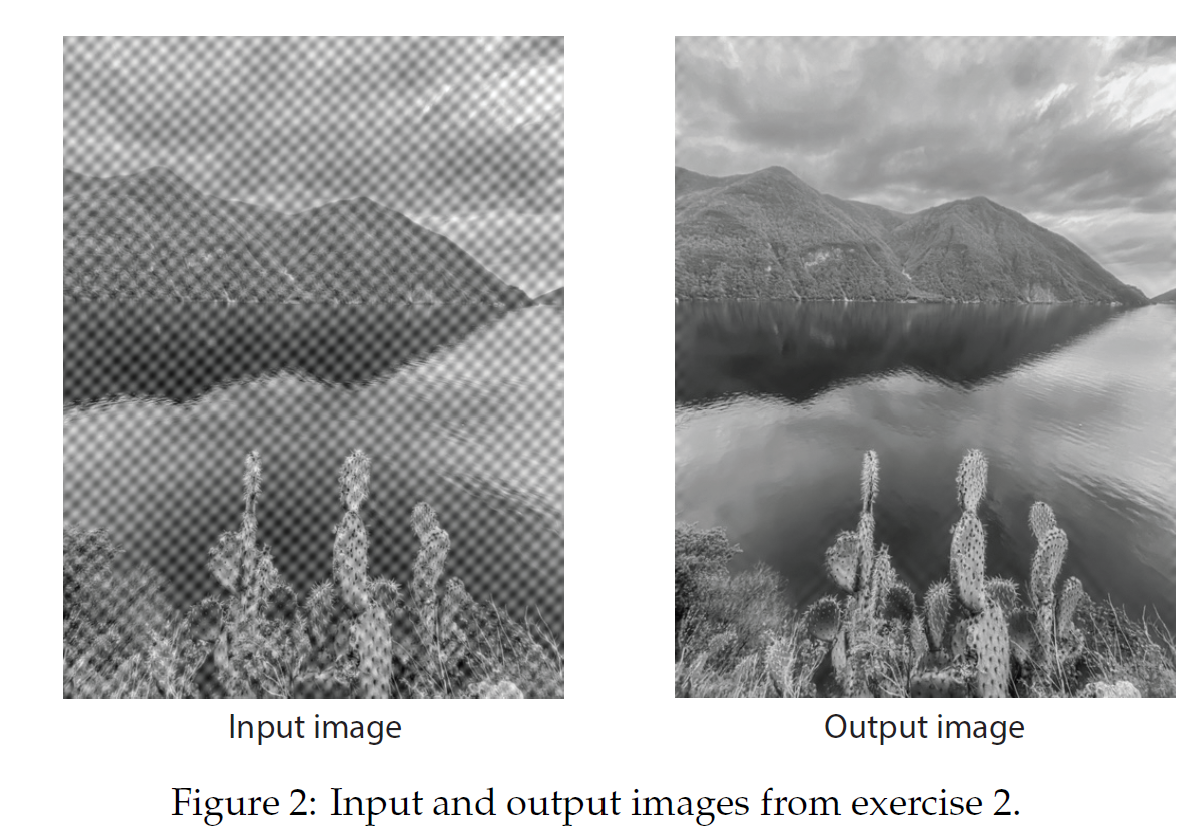

The input image San Domenico includes a repetitive pattern that appears as periodic noise. In the frequency domain, such patterns manifest as distinct peaks in the magnitude spectrum. To remove them while preserving image quality, the procedure is as follows.

The image is transformed using the Fourier transform and the magnitude spectrum is analyzed. Peaks representing the pattern are detected using thresholding. To avoid suppressing essential content, only peaks sufficiently far from the center, which corresponds to low-frequency information, are selected.

Gaussian notch filters are applied at the detected peaks to softly reduce their intensity and prevent harsh artifacts. Additionally, notch filtering effectively suppresses residual grid components. After filtering, the inverse Fourier transform is applied to return to the spatial domain and obtain the restored image.

The process is demonstrated step-by-step in the following figures.

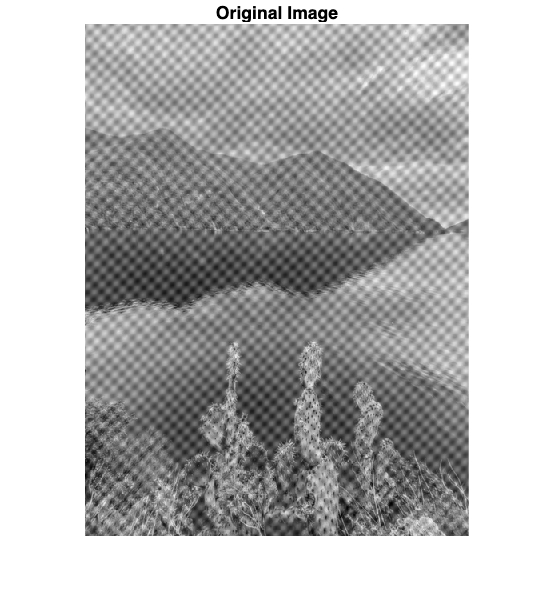

%% TASK 2: Image Restoration

%% Load
img = imread('san_domenico.png');
if size(img,3)==3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end

figure, imshow(img_gray), title('Original Image');

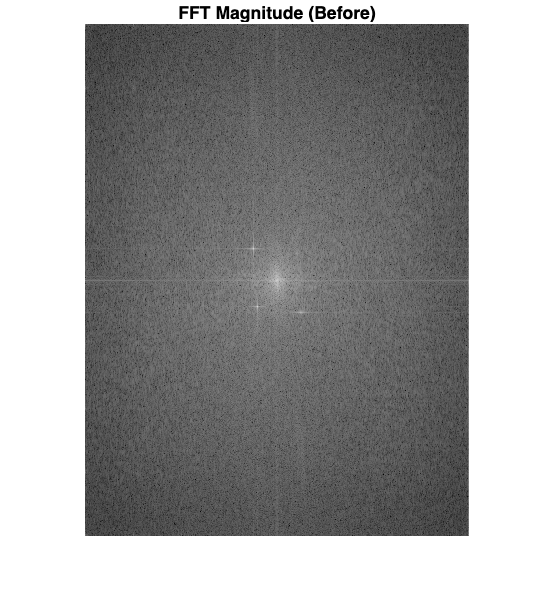


%% FFT
F = fft2(double(img_gray));
F_shifted = fftshift(F);
mag = log(1 + abs(F_shifted));

figure, imshow(mag, []), title('FFT Magnitude (Before)');

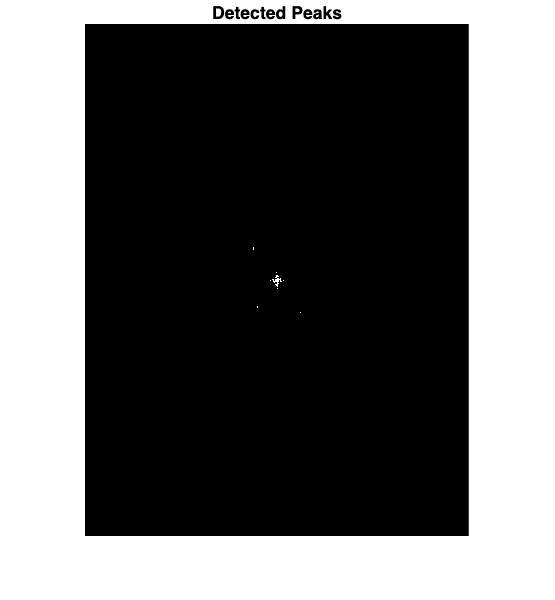


%% Peak Detection
threshold = mean(mag(:)) + 5;
peaks = mag > threshold;

figure, imshow(peaks), title('Detected Peaks');

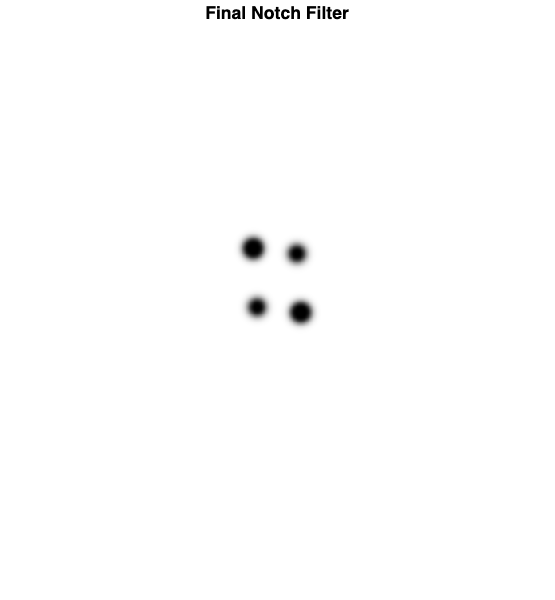


%% Build filter
[rows, cols] = size(img_gray);
[X, Y] = meshgrid(1:cols, 1:rows);
G = ones(rows, cols);

center_x = cols/2;
center_y = rows/2;

[py, px] = find(peaks);

for i = 1:length(px)
    cx = px(i);
    cy = py(i);
    
    % Distance from center
    dist = sqrt((cx - center_x)^2 + (cy - center_y)^2);
    
    if dist > 40
        sigma = 7; % Gaussian width
        gaussian = 1 - exp(-((X - cx).^2 + (Y - cy).^2) / (2 * sigma^2));
        G = G .* gaussian;
    end
end

figure, imshow(G, []), title('Final Notch Filter');

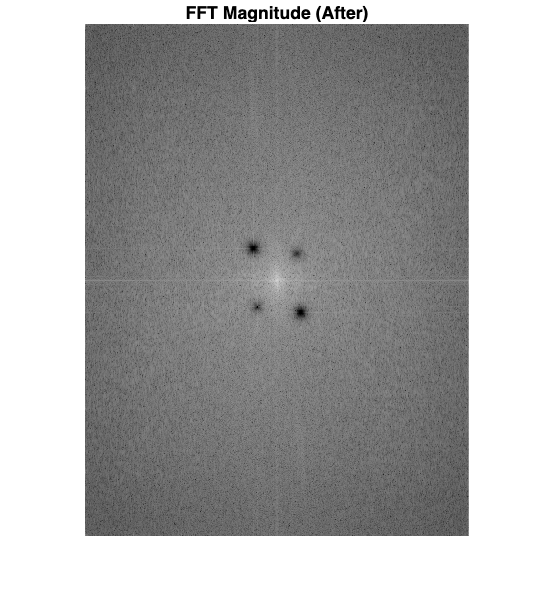


%% Apply Filter
F_filtered = F_shifted .* G;

mag_filtered = log(1 + abs(F_filtered));
figure, imshow(mag_filtered, []), title('FFT Magnitude (After)');

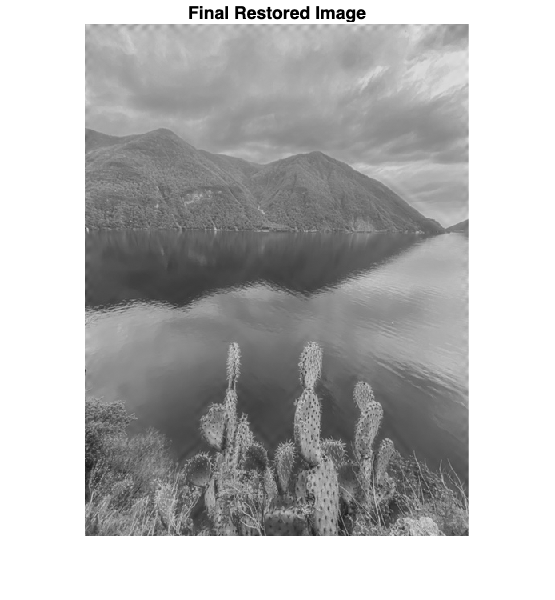


%% Inverse FFT
F_inv = ifftshift(F_filtered);
img_restored = real(ifft2(F_inv));

figure, imshow(uint8(img_restored)), title('Final Restored Image');

The results confirm that the repetitive pattern has been effectively removed. The filtered magnitude spectrum shows suppressed peaks and the restored image appears clean and natural. Grid artifacts are no longer visible and important image details, as well as brightness, are preserved. The outcome closely matches the expected result provided in the assignment.